# [量子计算简介](https://ww2.mathworks.cn/help/matlab/math/introduction-to-quantum-computing.html)

量子计算是一种新兴技术，它使用量子物理定律来执行计算。量子计算使用量子物理学中的现象，例如**叠加**和**纠缠**来执行计算。与信息存储为只能处于 0 或 1 状态的二进制位的经典计算不同，量子计算使用量子位或*qubits*，它可以同时处于 0 和*1*状态。由于这种根本差异，在解决某些类型的问题（例如优化或模拟）时，量子计算机有可能超越经典计算机。

本主题介绍了量子计算的三个构建块：量子位、量子门和量子电路。本主题还展示了如何执行量子电路的测量，方法是通过使用随机采样在本地模拟电路，或者通过在量子设备上远程运行电路。

## **量子比特**

量子比特是量子计算的基本构建块。量子比特存储信息，可以通过双态量子器件物理实现。一个量子比特可以是以下的线性组合`∣``0``⟩`和`∣``1``⟩`具有复数系数的状态，称为 *叠加*。如果复数系数被归一化，则它们表示测量量子位的概率幅度`∣``0``⟩`或者`∣``1``⟩`状态。例如，一个量子位可以在`我``∣``0``⟩``−``√``2``∣``1``⟩``√``3`状态。您可以确定测量量子位的概率`∣``0``⟩`通过取概率振幅的幅度平方来表示状态`∣``0``⟩`状态，即 1/3。同样，测量量子比特的概率`∣``1``⟩`状态是 2/3。

### **在布洛赫球体中可视化单个量子比特的状态**

布洛赫球体表示参数`我`和`φ`在球面坐标系中，分别表示单位球体相对于`z`轴的余纬度和相对于 `x轴的经度。`状态被绘制为一个点`在`在有坐标的单位球面上

`∣``ψ``⟩=cos``θ``2∣0⟩+exp(``i` `ϕ``)sin``θ``2∣1⟩.`

按照惯例，北极是`∣``0``⟩`状态，南极是`∣``1``⟩`状态，赤道是这两个状态的线性组合，测量概率相等`∣``0``⟩`或者`∣``1``⟩`.

`u``=(sin``θ``cos``ϕ``,sin``θ``sin``ϕ``,cos``θ``).`

要在 Bloch 球体上绘制量子位的任何量子态，请使用函数 `plotBlochSphere`（在[辅助函数](https://ww2.mathworks.cn/help/matlab/math/introduction-to-quantum-computing.html#mw_8943f9aa-da7e-45cf-9de8-1e91ff5ccffb)部分中提供）。此函数采用具有两个元素的复数向量，这两个元素表示`∣``0``⟩`和`∣``1``⟩`状态。

例如，绘制`∣``0``⟩`布洛赫球面上的状态。

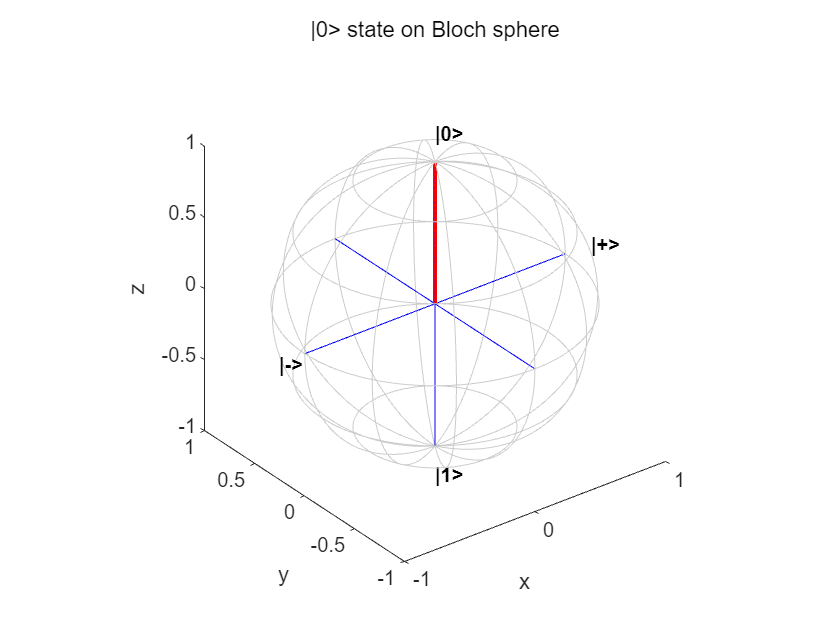

plotBlochSphere([1; 0])
title("|0> state on Bloch sphere")

绘制`∣1⟩`布洛赫球面上的状态。

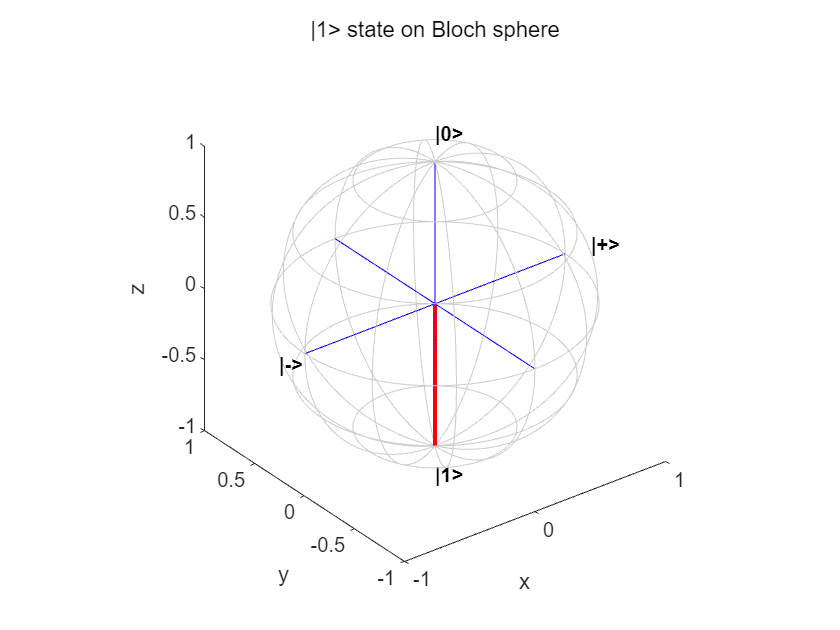

plotBlochSphere([0; 1])
title("|1> state on Bloch sphere")

绘制`∣+⟩=(∣0⟩+∣1⟩)/√2`布洛赫球面上的状态。这种状态由赤道上的一个点表示。它在球体另一侧的相对点代表`∣−⟩` 状态。

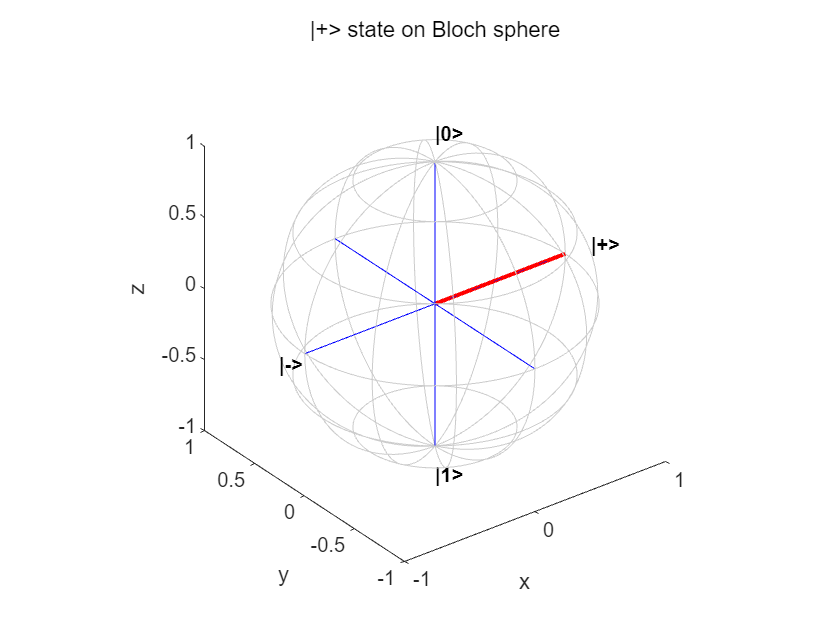

plotBlochSphere([1; 1]/sqrt(2))
title("|+> state on Bloch sphere")

绘制`∣−⟩=(∣0⟩−∣1⟩)/√2`布洛赫球面上的状态。

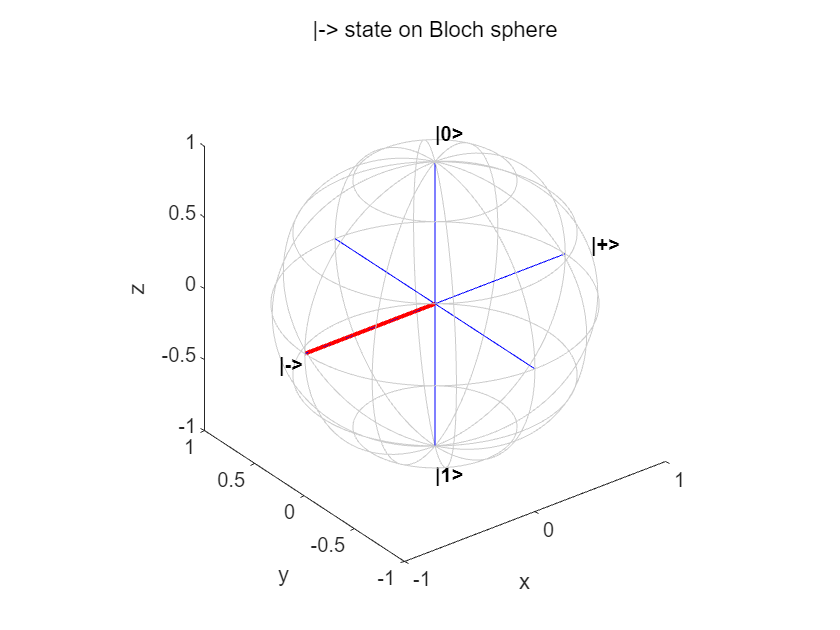

plotBlochSphere([1; -1]/sqrt(2))
title("|-> state on Bloch sphere")

绘制`∣``R``⟩=(∣0⟩+``我``∣1⟩)/√2`布洛赫球面上的状态。

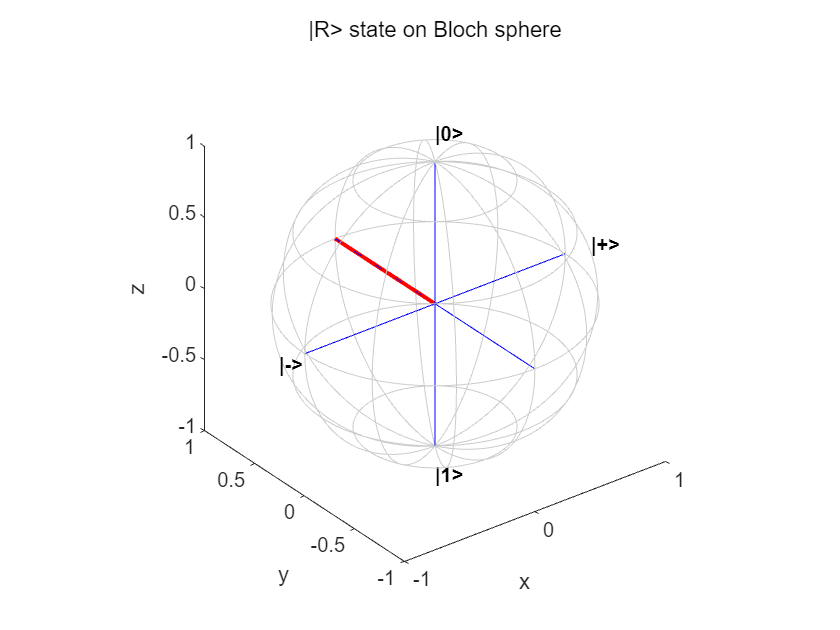

plotBlochSphere([1; 1i]/sqrt(2))
title("|R> state on Bloch sphere")

绘制`∣``大号``⟩=(∣0⟩-``我``∣1⟩)/√2`布洛赫球面上的状态。

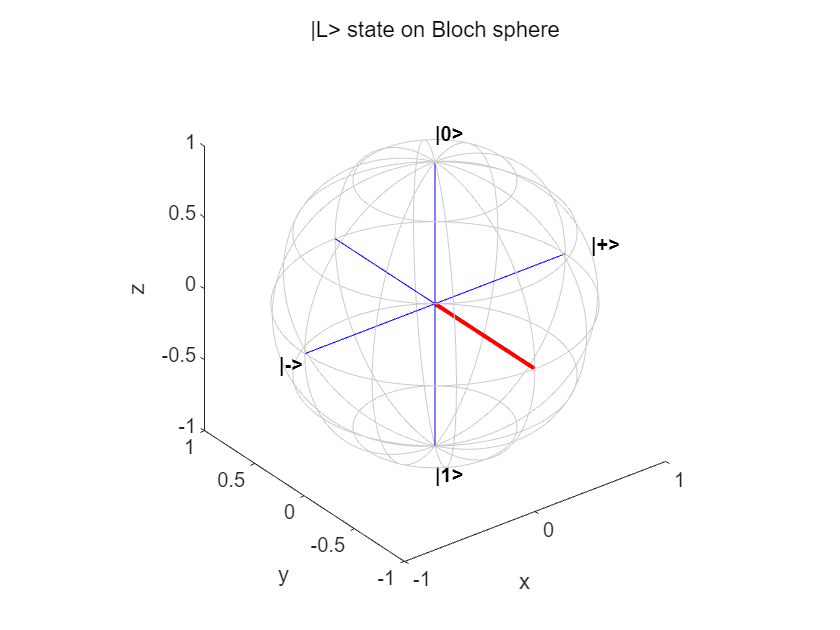

plotBlochSphere([1; -1i]/sqrt(2))
title("|L> state on Bloch sphere")

## **找到测量可能状态的概率**

单个量子位的量子态表示为归一化的双元素复向量，其中第一个元素给出了`∣``0``⟩`状态和第二个元素给出的振幅`∣``1``⟩`状态。这个量子比特的测量产生了一个经典的`∣``0``⟩`或者`∣``1``⟩`状态，测量每个状态的概率由其各自幅度的平方给出。

您可以使用[`quantum.gate.QuantumState`](https://ww2.mathworks.cn/help/matlab/ref/quantum.gate.quantumstate-class.html)构造函数创建一个量子态，然后使用该[`querystates`](https://ww2.mathworks.cn/help/matlab/ref/quantum.gate.quantumstate.querystates.html) 函数找到要测量的可能状态及其概率。例如，创建一个代表`∣``1``⟩`状态。

state = quantum.gate.QuantumState([0 1]);
state.Amplitudes

ans =      0
     1


该`querystates`函数返回要测量的所有可能状态以及测量每个状态的概率。在这里，只有`∣1⟩`状态是可能的。

[states,probabilities] = querystates(state)

states = "1"

probabilities = 1

作为另一个示例，创建一个量子态，其中向量的两个元素具有不同的振幅和相同的绝对值。

state = quantum.gate.QuantumState([1 1i]/sqrt(2));
state.Amplitudes

ans =    0.7071 + 0.0000i
   0.0000 + 0.7071i


该`querystates`函数返回`"0"`和 `"1"`状态作为要测量的可能状态以及测量每个状态的 0.5 概率。

[states,probabilities] = querystates(state)

states = 2×1 string 数组
    "0"
    "1"


probabilities =     0.5000
    0.5000


您可以使用 绘制直方图，显示测量所有可能状态的概率[`histogram`](https://ww2.mathworks.cn/help/matlab/ref/quantum.gate.quantumstate.histogram.html)。

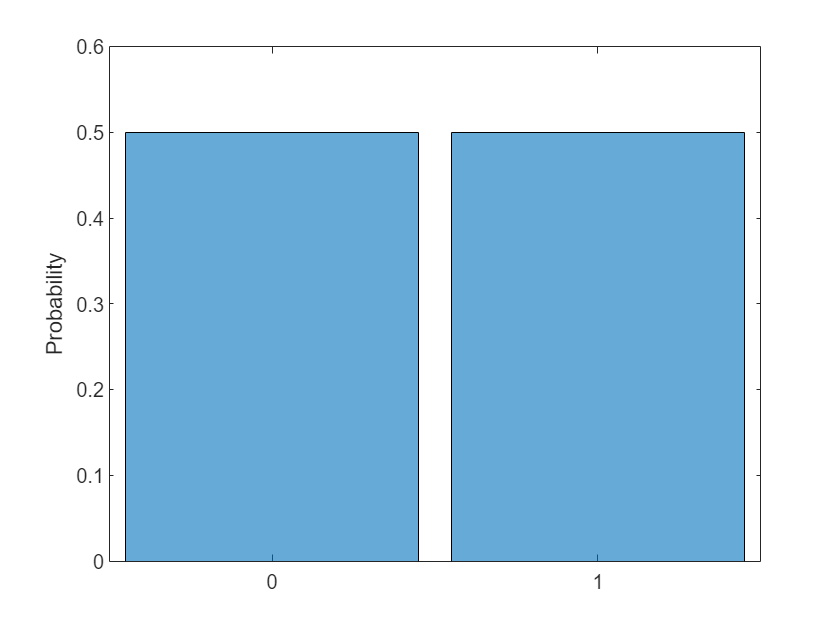

histogram(state)

作为另一个示例，创建一个量子态，其中矢量的两个元素具有不同的振幅和不同的绝对值。如果您 `quantum.gate.QuantumState`使用一般复数向量调用，则构造函数会创建一个标准化的量子态。例如，创建一个量子态并找到它的测量概率。

state = quantum.gate.QuantumState([3 -4i]);
state.Amplitudes

ans =    0.6000 + 0.0000i
   0.0000 - 0.8000i


[states,probabilities] = querystates(state)

states = 2×1 string 数组
    "0"
    "1"


probabilities =     0.3600
    0.6400


只有转化为概率的量子态属性是可测量的。例如，将量子态的每个振幅乘以 –1 或`exp(i ``θ ``)`没有可衡量的影响。这种类型的转换称为应用*全局阶段*。但是，将其中一个振幅乘以 –1 或`exp(i ``θ ``)`（应用*相对相位*）具有可衡量的影响。如果在应用相对相位后直接测量状态，则看不到概率的差异。但是，如果您在量子位上应用额外的门操作，您可以检测到由于相对相位引起的差异。

## **量子门**

量子门是量子计算的下一个组成部分。量子门表示根据酉矩阵转换量子态的可逆操作。虽然所有门操作都是确定性的，但量子计算中的测量是概率性的，各种测量的概率取决于量子位的状态。有关 MATLAB 中可用的量子门的完整列表，请参阅[量子门的类型](https://ww2.mathworks.cn/help/matlab/math/types-of-quantum-gates.html)。

### **保利 X 门**

量子门的一个例子是 Pauli X 门。这个门将状态向量乘以 Pauli X 矩阵`[``0``1``1``0``]`, 这会翻转`∣``0``⟩`一个量子比特的状态`∣``1``⟩`国家和翻转`∣``1``⟩`国家对`∣``0``⟩`状态。

例如，创建单个量子位的初始量子态。

coeffs = [0.7; 0.5i];
inState = quantum.gate.QuantumState(coeffs);
inAmps = inState.Amplitudes

inAmps =    0.8137 + 0.0000i
   0.0000 + 0.5812i


创建一个量子电路，通过使用 将 Pauli X 门 ( [`xGate`](https://ww2.mathworks.cn/help/matlab/ref/xgate.html)) 应用于量子位[`quantumCircuit`](https://ww2.mathworks.cn/help/matlab/ref/quantumcircuit.html)。使用 模拟此电路以获得量子比特的最终状态[`simulate`](https://ww2.mathworks.cn/help/matlab/ref/quantumcircuit.simulate.html)。

c = quantumCircuit(xGate(1));
outState = simulate(c,inState);
outAmps = outState.Amplitudes

outAmps =    0.0000 + 0.5812i
   0.8137 + 0.0000i


为了说明 Pauli X 门执行的操作，请在 Bloch 球体上绘制电路的初始状态和最终状态。在 Bloch 球体表示中，泡利 X 门围绕`x`轴旋转状态（`∣+⟩`和`∣−⟩`状态）的角度`π`.

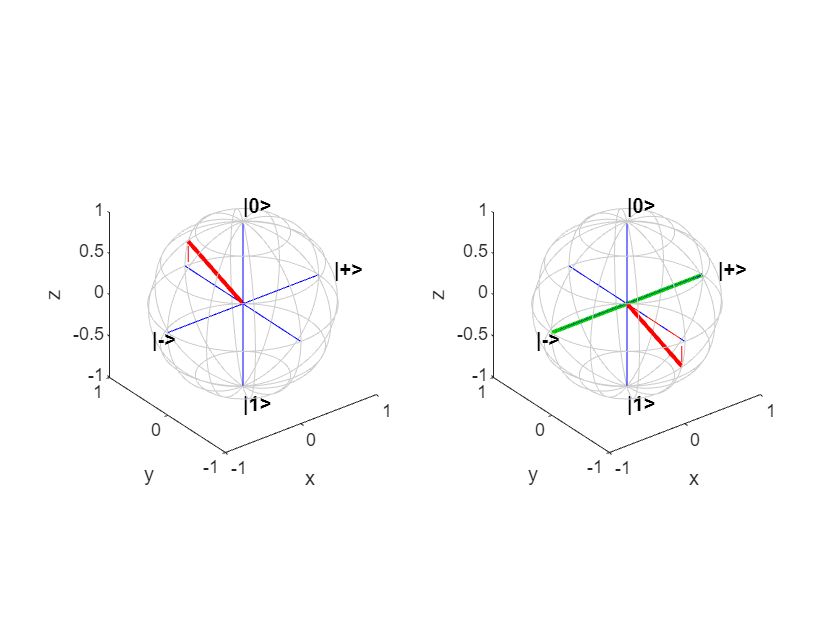

figure
tiledlayout(1,2);
nexttile
plotBlochSphere(inAmps)
nexttile
plotBlochSphere(outAmps)
hold on
plot3([-1 1],[0 0],[0 0],LineWidth=2,Color=[0 0.8 0])
hold off

对于量子比特基态的选择，`∣``0``⟩`和`∣``1``⟩`态是 Pauli Z 门的本征态。应用 Pauli Z 门 ( [`zGate`](https://ww2.mathworks.cn/help/matlab/ref/zgate.html)) 对`∣``0``⟩`状态和映射`∣``1``⟩`状态`−``∣``1``⟩`. 泡利 Z 门也称为相位翻转门。同样，`∣``+``⟩`和`∣``−``⟩`状态是 Pauli X 门的本征态。泡利 Y 门 ( [`yGate`](https://ww2.mathworks.cn/help/matlab/ref/ygate.html)) 的本征态是图中另外两个正交方向，它们是`∣``R``⟩``=``(``∣``0``⟩``+``我``∣``1``⟩``)``/``√``2`状态和`∣``大号``⟩``=``(``∣``0``⟩``-``我``∣``1``⟩``)``/``√``2`状态。虽然这些对中的每一对都可以作为基础状态，但`∣``0``⟩`和`∣``1``⟩`基态是进行测量的标准基态。要以任意角度 围绕`x`、`y`或 `z`[`rxGate`](https://ww2.mathworks.cn/help/matlab/ref/rxgate.html)轴旋转，您可以使用旋转门、 [`ryGate`](https://ww2.mathworks.cn/help/matlab/ref/rygate.html)或 [`rzGate`](https://ww2.mathworks.cn/help/matlab/ref/rzgate.html)。

### **阿达玛门**

量子门的另一个例子是 Hadamard 门，它将 Z 基转换为 X 基。也就是说，门转换`∣``0``⟩`和`∣``1``⟩`国家对`∣``+``⟩`和`∣``−``⟩`州，分别。例如，考虑先前创建的相同初始量子态。

inAmps = inState.Amplitudes

inAmps =    0.8137 + 0.0000i
   0.0000 + 0.5812i


创建一个将 Hadamard 门 ( [`hGate`](https://ww2.mathworks.cn/help/matlab/ref/hgate.html)) 应用于量子位的量子电路。仿真此电路以获得量子位的最终状态。

c = quantumCircuit(hGate(1));
outState = simulate(c,inState);
outAmps = outState.Amplitudes

outAmps =    0.5754 + 0.4110i
   0.5754 - 0.4110i


从状态的概率幅度来看，Hadamard 门的操作并不明显。[为了更好地理解此操作，请使用函数（在“辅助函数](https://ww2.mathworks.cn/help/matlab/math/introduction-to-quantum-computing.html#mw_8943f9aa-da7e-45cf-9de8-1e91ff5ccffb)`mapToBlochSphere`”部分中提供）将状态的复振幅转换为布洛赫球体上的坐标 。显示 Bloch 球体上初始状态和最终状态的坐标。

inCoords = mapToBlochSphere(inAmps)

inCoords =     0.0000    0.9459    0.3243


outCoords = mapToBlochSphere(outAmps)

outCoords =     0.3243   -0.9459    0.0000


在 Bloch 球体表示中，Hadamard 门将状态围绕 [1,0,1] 轴旋转一个角度`π`.

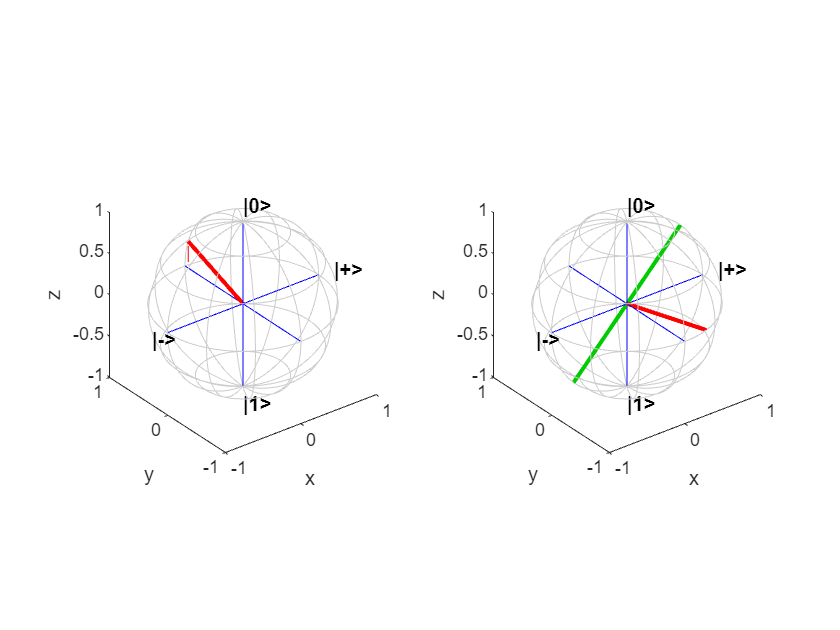

figure
tiledlayout(1,2);
nexttile
plotBlochSphere(inAmps)
nexttile
plotBlochSphere(outAmps)
hold on
plot3([-1 1]/sqrt(2),[0 0],[-1 1]/sqrt(2),LineWidth=2,Color=[0,0.8,0])
hold off

量子设备通常仅在 Z 基中提供测量，考虑到使用量子门可用的各种转换，这是一种本质上并不特殊的基选择。例如，要在 X 基中测量一个量子位，您可以在执行测量之前对量子位应用阿达玛门。

### **量子电路**

量子电路是量子计算的下一个组成部分。量子电路由作用于量子比特的量子门组成。量子电路图通常用作应用于量子位的一系列量子门的视觉模型。这个量子电路图示例包括一个 Hadamard 门和一个作用于两个量子位的受控 X 门。

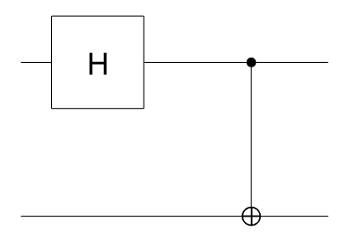

- 在量子电路图中，每条水平实线代表一个量子位，或者更笼统地说，一个量子位寄存器。在 MATLAB 中，顶行是索引为 1 的量子位，其余行从上到下按顺序标记。在此示例中，电路由索引为 1 和 2 的两个量子位组成。

- 量子门对量子位执行操作。作用于量子位的门表示为特定的门符号。在这个例子中，符号表示作用于量子位 1 的阿达玛门。下一个符号表示一个受控的 X 门，其中量子位 1 作为控制，量子位 2 作为目标。

- 在电路图中，时间从左向右流动。量子门按时间顺序排列，最左边的门是首先应用于量子位的门。水平实线表示从左到右通过图中每个门的电路的整体量子态。

- `对于具有n 个`量子位的量子电路，整体`2``n``基态由n 个`量子比特基的 Kronecker 积构成， 对于具有最低索引到最高索引的量子比特，从左到右排序。换句话说，如果索引为`k`的单个量子位的基被标记为`∣``∣``q``k``⟩`（可以是`∣``0``⟩`或者`∣``1``⟩``), 那么具有n 个`量子比特的电路的基态 表示为`∣``∣``q``1``⟩``⊗``...``⊗``∣``∣``q``k``⟩``⊗``...``⊗``∣``∣``q``n``⟩`. 例如，对于具有两个量子位的电路，表示为列向量的所有可能基态是`∣``∣``q``1``q``2``⟩``=``[``∣``00``⟩``,``∣``01``⟩``,``∣``10``⟩``,``∣``11``⟩``]``吨`. 这个定义遵循大多数教科书。

- 门操作可以表示为这些基态的变换矩阵。例如，考虑基于控制量子位（索引为 1）的状态在目标量子位（索引为 2）上运行的受控 X 门。如果控制量子位在`∣``0``⟩`状态，这个门什么都不做。如果控制量子位在`∣``1``⟩`状态，此门将 Pauli X 门应用于目标量子位。受控 X 门的矩阵表示为`⎡``⎢``⎢``⎢``⎢``⎣``1``0``0``0``0``1``0``0``0``0``0``1``0``0``1``0``⎤``⎥``⎥``⎥``⎥``⎦``.`

- `具有n 个`量子位的电路的量子态可以用以下的线性组合来表示`2``n`基态，可以是可分离态或纠缠态。*可分离*态 是一种量子态，可以分解为属于量子位的独立子空间的各个状态。纠缠 *态*是不可分离的量子态。例如，对于具有两个量子位的电路，量子态可以是可分离的状态，例如`我``2``(``∣``00``⟩``+``∣``01``⟩``+``∣``10``⟩``+``∣``11``⟩``)``=``(``∣``0``⟩``+``∣``1``⟩``)``√``2` `我``(``∣``0``⟩``+``∣``1``⟩``)``√``2`其中量子位 1 在`∣``+``⟩``=``(``∣``0``⟩``+``∣``1``⟩``)``/``√``2`状态和量子位 2 在`我``(``∣``0``⟩``+``∣``1``⟩``)``/``√``2`状态。两个量子比特的量子态也可以是纠缠态，比如`1``/``√``2` `(``∣``00``⟩``+``∣``11``⟩``)`，不能写成每个量子比特状态的乘积。对于这种纠缠态，两个量子比特是一个不可分割的整体。如果这些量子位之一在`∣``0``⟩`状态，那么另一个量子比特也将在`∣``0``⟩`状态。类似地，如果这些量子位之一在`∣``1``⟩`状态，那么另一个量子比特也将在`∣``1``⟩`状态。

- 默认情况下，量子电路中每个量子比特的初始状态是`∣``0``⟩`状态。例如，图中量子电路的初始状态为`∣``00``⟩`. 经过 Hadamard 和受控 X 门的运算后，电路的最终状态为纠缠态，`1``/``√``2` `(``∣``00``⟩``+``∣``11``⟩``)`.

### **构建和模拟量子电路**

您可以使用该[`quantumCircuit`](https://ww2.mathworks.cn/help/matlab/ref/quantumcircuit.html) 函数构建量子电路。创建一个具有两个量子位的空量子电路。模拟此电路返回的量子态。使用 将此电路的量子态显示为字符串公式[`formula`](https://ww2.mathworks.cn/help/matlab/ref/quantum.gate.quantumstate.formula.html)。

c = quantumCircuit(2);
s = simulate(c);
str = formula(s)

str = "1 * |00>"

默认情况下，所有量子位都设置为 0。接下来，传递一个不同的初始量子态，`12(∣00⟩−∣01⟩)+1i ``_``2(∣10⟩−∣11⟩)`, 到`simulate`函数，其中量子态是量子位所有基态的线性组合。

inState = quantum.gate.QuantumState([1/2; -1/2; 1i/2; -1i/2]);
s = simulate(c,inState);
str = formula(s,Basis="Z")

str =     "(0.5+0i)  * |00> +
     (-0.5+0i) * |01> +
     (0+0.5i)  * |10> +
     (0-0.5i)  * |11>"


您可以在电路中添加量子门。对于此示例，将受控 X（或 CNOT）门添加到电路中。然后绘制电路。

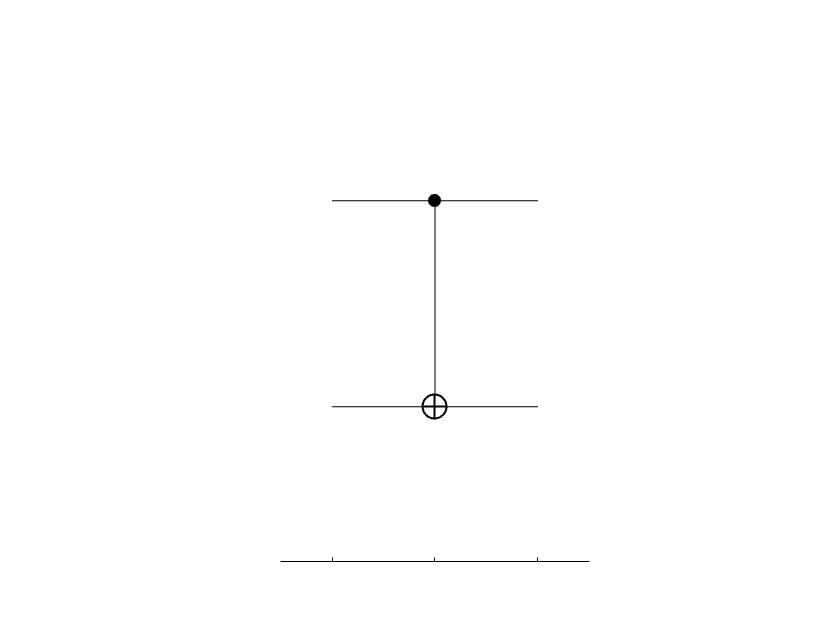

c.Gates = cxGate(1,2);
figure
plot(c)

通过初始状态后找到此电路的最终状态`12(∣00⟩−∣01⟩)+1i ``_``2(∣10⟩−∣11⟩)`到受控的 X 门。

outState = simulate(c,inState);
str = formula(outState,Basis="Z")

str =     "(0.5+0i)  * |00> +
     (-0.5+0i) * |01> +
     (0-0.5i)  * |10> +
     (0+0.5i)  * |11>"


您也可以将初始状态传递为`∣+0⟩`到这个电路。找到此初始状态的此电路的最终状态。

outState = simulate(c,"+0");
str = formula(outState,Basis="Z")

str =     "0.70711 * |00> +
     0.70711 * |11>"


### **运行电路并进行测量**

您可以在远程量子设备上运行内置在 MATLAB 中的电路并检索测量结果。

使用 Hadamard 门和受控 X 门构建纠缠两个量子位的量子电路。然后绘制电路。

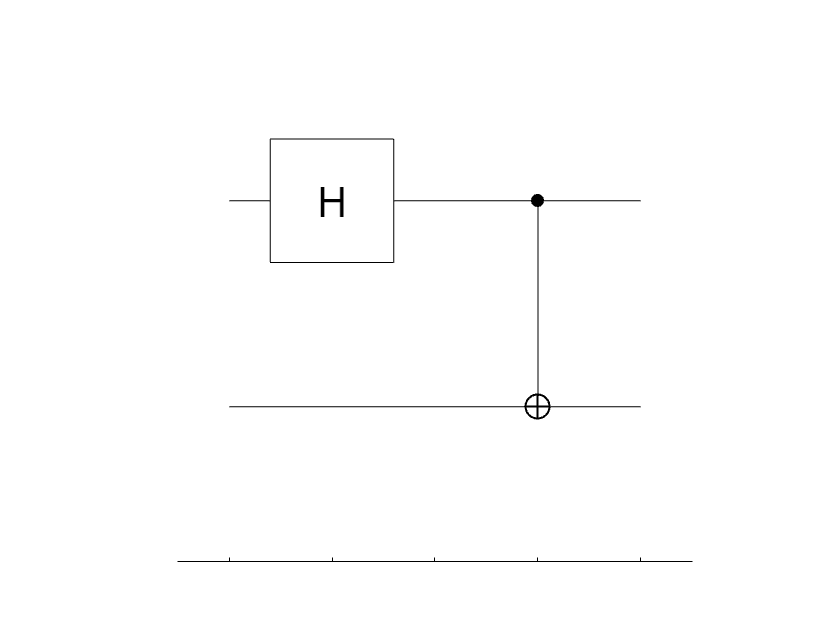

gates = [hGate(1); cxGate(1,2)];
c = quantumCircuit(gates);
plot(c)

该电路的默认初始状态是`∣00⟩`. 仿真电路以获得其最终状态。

outState = simulate(c);
str = formula(outState)

str =     "0.70711 * |00> +
     0.70711 * |11>"


要研究此电路的行为，您可以先对电路进行本地模拟测量。用于[`randsample`](https://ww2.mathworks.cn/help/matlab/ref/quantum.gate.quantumstate.randsample.html)对电路的量子态进行 100 次随机采样。

m = randsample(outState,100)

m =   QuantumMeasurement - 属性:

    MeasuredStates: [2×1 string]
            Counts: [2×1 double]
         NumQubits: 2


显示测量的状态及其计数。

table(m.Counts,m.MeasuredStates,VariableNames=["Counts","States"])

ans = 2×2 table
    Counts    States
    ______    ______

      56       "00" 
      44       "11" 


理论上，因为量子态是纠缠的，它只是`∣``00``⟩`和`∣``11``⟩`状态，测量的概率`∣``01``⟩`和`∣``10``⟩`states 为 0。然而，在实践中，由于迄今为止物理量子设备中的噪声，`∣``01``⟩`和`∣``10``⟩`状态可以显示为测量值。

要在可通过 Amazon ® Web Services (AWS ® )获得的远程量子设备上运行电路，首先使用连接到特定的量子设备[`quantum.backend.QuantumDeviceAWS`](https://ww2.mathworks.cn/help/matlab/ref/quantum.backend.quantumdeviceaws-class.html)。

% dev = quantum.backend.QuantumDeviceAWS("Aspen-M-3");

使用该函数以默认 100 次拍摄在设备上运行电路[`run`](https://ww2.mathworks.cn/help/matlab/ref/quantumcircuit.run.html) 。

% task = run(c,dev)

等待任务完成。使用 检索在设备上运行电路的测量结果[`fetchOutput`](https://ww2.mathworks.cn/help/matlab/ref/quantum.backend.quantumtaskaws.fetchoutput.html)。

% wait(task)
% m = fetchOutput(task)

显示测量结果。由于量子器件中的噪声，`∣01⟩`和`∣10⟩`状态显示为测量值。

% table(m.Counts,m.MeasuredStates,VariableNames=["Counts","States"])

### **辅助功能**

`plotBlochSphere`本节提供和 函数的完整代码`mapToBlochSphere`。

function plotBlochSphere(u)
% Plot Bloch sphere representation from 2-D complex amplitudes

%   Copyright 2021-2023 The MathWorks, Inc.

arguments
    u {mustBeNumeric,mustBeVector}
end

% Compute Bloch sphere representation (3-D real) from a 2-D complex vector
P = mapToBlochSphere(u);

% Grid view of the sphere
alpha = linspace(0,2,101)';
alpha(end+1) = NaN;
beta = linspace(0,1,7);
beta(end) = [];
gamma = linspace(-0.5,0.5,7);

% Meridian lines
meridianCoordinates = cat(3, cospi(beta).*cospi(alpha), ...
    sinpi(beta).*cospi(alpha), repmat(sinpi(alpha), 1, length(beta)));

% Latitude circles
latitudeCoordinates = cat(3, cospi(gamma).*cospi(alpha), ...
    cospi(gamma).*sinpi(alpha), repmat(sinpi(gamma), length(alpha), 1));

xyz = [reshape(meridianCoordinates,[],3); reshape(latitudeCoordinates,[],3)];

% Plot the grid and coordinate system
plot3(xyz(:,1), xyz(:,2), xyz(:,3), "k-", Color=0.8*[1 1 1])
hold on
plot3([1 0 0; -1 0 0], [0 1 0; 0 -1 0], [0 0 1; 0 0 -1], "b")

% Label qubit basis vectors for X basis and Z basis
text([0 0 1.2 -1.2], [0 0 0 0], [1.2 -1.2 0 0], ["|0>" "|1>" "|+>" "|->"], ...
    FontWeight="bold")

% Configure axis view
xlabel("x")
ylabel("y")
zlabel("z")
axis equal

% Plot the vector
plot3([0 P(1)], [0 P(2)], [0 P(3)], "r-", LineWidth=2)
plot3([0 P(1) P(1)], [0 P(2) P(2)], [0 0 P(3)], "r--")

hold off
end


function P = mapToBlochSphere(u)
% Compute Bloch sphere representation (3-D real) from a 2-D complex vector

theta = 2*atan2(abs(u(2)),abs(u(1)));
phi = angle(u(2)*conj(u(1)));
P =  [sin(theta)*cos(phi) sin(theta)*sin(phi) cos(theta)];

end